**Stability Calculator**

Calculates stability at launch for a rocket with 3 'tapered delta' fins, with a planform defined by five length quantities (see diagram below). All variables can be calculated using OpenRocket or defined by the user. CoG and CP are measured from the tip of the nose cone. This uses calculations based on the OpenRocket technical documentation and gives values close to those calculated in OpenRocket, although should always be validated using OpenRocket.

Nomenclature (SI units)

D - maximum body diameter

h - distance from tip of the nose cone to the start of the fins (leading edge)

m - mass of the rocket without fins

G = centre of gravity of rocket without fins

T - average thickness of the profile of the fins (e.g. aerofoil thickness)

rho - density of the fin material

CN_NF - total CN_(alpha) of the rocket without fins

CP_NF - CP of the rocket without fins

S - span

A_ref - Referrence area defined in OpenRocket

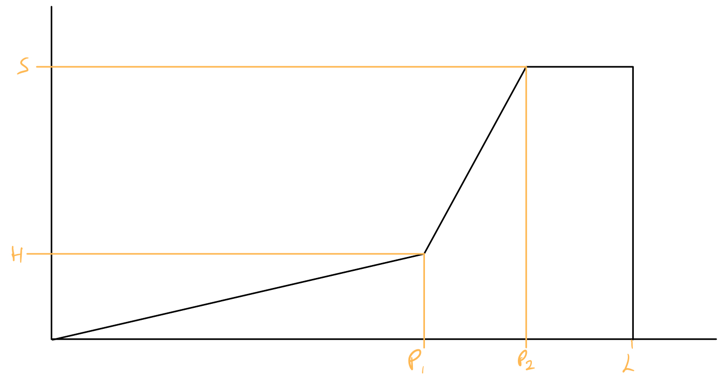

calculate function takes 5 variable inputs: span, chord at root, 'P2', 'P1', 'H' (see diagram above)

Stability = calculate(0.0455, 0.0762, 0.0671, 0.0454, 0.0142)

Stability = -0.8501

function stability = calculate(S, L, P2, P1, H)
%Variable definitions
D = 0.046;
m = 1.227;
G = 0.592;
T = 0.0025;
rho = 2700;
CN_NF = 2;
CP_NF = 0.1;
A_ref = 0.00166;
beta = 1;
h = 0.874-L;

%Centre of gravity calculations
A_fin = 0.5*H*P1+0.5*(H+S)*(P2-P1)+(L-P2)*S;
M = 3*T*rho*A_fin;
help = P2-P1;
G_fin = h+(3*T*rho*(((1/3)*H*P1^2)+(0.5*(S-H)*help*((2/3)*help+P1))+((0.5*(P2+P1))*H*help)+((0.5*(L+P2))*(L-P2)*S)))/M;
CG = (m*G+M*G_fin)/(m+M);

%CP calculations (fins)
fun1 = @(y) ((P1*y)/H).*(S-(P1*y)/H);
fun2 = @(y) (P1+(P2-P1)*(y-H)/(S-H)).*((L-P1)*(1-(y-H)*(P2-P1)/(S-H)));
CP_fins = h+(1/A_fin)*(integral(fun1,0,H)+integral(fun2, H, S));

%CN calculations
%Gives different (incorrect) result when calculated in one sum
sweep = (atan2d((L-P1),(2*H))+atan2d((L-P2),(2*(S-H))))/2;
a = 2*pi;
b = S^2;
c = b/A_ref;
d = beta*b;
e = A_fin*cosd(sweep);
f = d/e;
g = f^2;
h = 1+g;
i = sqrt(h);
j = 1+i;
k = a*c;
l = k/j;
CN_fins = l*2;

%CP calculations (total)
Cma_NF = CP_NF*CN_NF;
Cma_fins = CP_fins*CN_fins;
CP = ((Cma_NF+Cma_fins)/(CN_NF+CN_fins));

%Stability & results
stability = (CG-CP)/D;
end